data = readtable("30102_mic_data", 'Format', "%s", 'ReadVariablenames', false, "Delimiter", "comma");
ir_vals = [];
red_vals = [];
sound_vals = [];

% skip first row
for i=2:length(data.Var1)
    token_array = regexp(data.Var1(i), "(-?\d*)", 'tokens');
    % token_array = regexp(data.Var1(i), ".* -> [A-z :]*(-?\d*)", 'tokens');
    token = token_array{1};
    num = str2double(token{1});
    if ~isnan(num)
        if contains(data.Var1(i), "IR VAL:") && contains(data.Var1(i), "RED VAL:")
            num2 = str2double(token{2});
            red_vals = [red_vals, num];
            ir_vals = [ir_vals, num2];
        elseif contains(data.Var1(i), "IR VAL:")
            ir_vals = [ir_vals, num];
        elseif contains(data.Var1(i), "RED VAL:")
            red_vals = [red_vals, num];
        else
            sound_vals = [sound_vals, num];
        end
    end
end


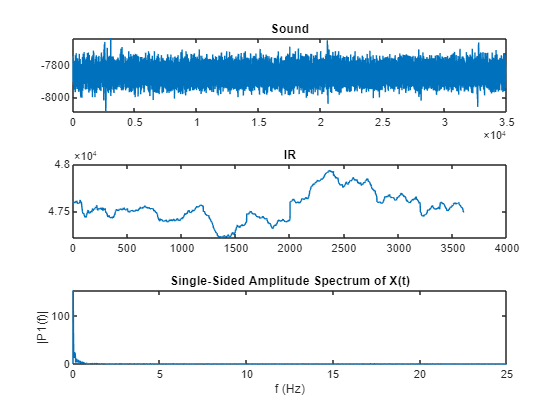

Y = fft(red_vals-mean(red_vals));
L = length(red_vals);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1)  
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

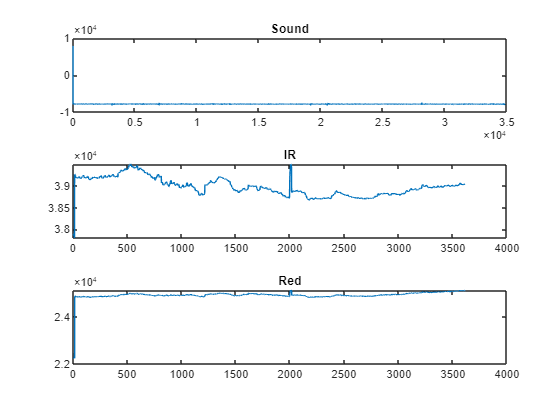

subplot(3,1,1)
plot(sound_vals)
title("Sound")
subplot(3,1,2)
plot(ir_vals)
title("IR")
%ylim([3.75e4 3.8e4])
subplot(3,1,3)
plot(red_vals)
title("Red")

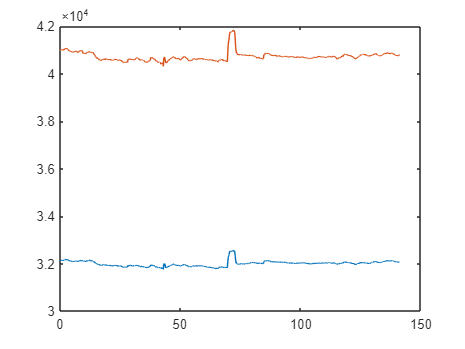

Hr_time=linspace(0,length(red_vals)*0.047,length(red_vals));
sound_time= linspace(0,length(sound_vals)*0.004462,length(sound_vals)); 
figure
plot(Hr_time, red_vals);
hold on
plot(Hr_time, ir_vals);
hold off

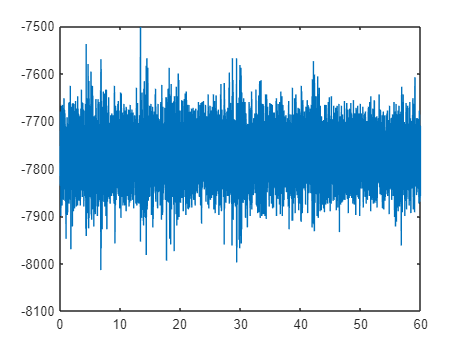

figure
plot(sound_time, sound_vals);

The reason why we are doing linspace is to create artifical time array to plot our values.

Basing it off the HR array (1x7633 double) and we are assuming time ticks of 0.01s, we can calculate the length of the sample we are

taking which is going to be $\textrm{length}\;\textrm{time}\;\textrm{of}\;\textrm{sample}=\textrm{Length}\;\textrm{of}\;\textrm{array}\;\left(7633\right)*\;\textrm{timestep}\;\left(0\ldotp 01\right)=76\ldotp 3\;\textrm{seconds}$

To create the same time for the sound, we need to determine the sound timestep which can be found by


$$\textrm{sound}{\;}_{\textrm{time}\;\textrm{step}} =\frac{\textrm{length}\;\textrm{of}\;\textrm{time}\;\textrm{sample}}{\;\textrm{array}\;\textrm{length}\;\textrm{of}\;{\textrm{sound}}_{\textrm{vals}} }=\frac{76\ldotp 3}{80400}=0\ldotp 000949\;s$$
